# Small Network With All Delays

## first, setup connctivity map

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision-2Drive'

FigurePath = [CurrentFolder '/Figures'];
FigureNowPath = [CurrentFolder '/Figures/Demo051421/'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
DataFolder = [pwd '/Data/SNWData/'];
addpath(DataFolder)

% Make sure the old stuff is the same
load('NtWk_Archit.mat')
E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
[E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
[I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);

N_EE = full(mean(sum(C_EE(E_Ind,:),2))); N_EI = full(mean(sum(C_EI(E_Ind,:),2))*0.75); 
N_IE = full(mean(sum(C_IE(I_Ind,:),2))); N_II = full(mean(sum(C_II(I_Ind,:),2))*0.75); %Plan A:Original
                                                                                       %Plan B: Lower #ItoE and #I-to-I

% Now Make a small network s.t. the mean presynaptic neurons are equal to
% above
N_E = floor(3*N_IE); N_I = floor(1/3*N_E);
CS_EE = SmallNetworkGenerat(N_E,N_E,N_EE);
CS_IE = SmallNetworkGenerat(N_E,N_I,N_IE);
CS_EI = SmallNetworkGenerat(N_I,N_E,N_EI);
CS_II = SmallNetworkGenerat(N_I,N_I,N_II);

## Variables and Parameters

fixed parameters

DataSuffix = 'Hpp';

p_EEFail = 0.2; S_amb = 0.01;
rE_amb = 0.500; rI_amb = 0.500;

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80; % 80
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms

gL_E = 1/20;  Ve = 14/3; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

NW Connectivity and L6 Input

S_EE = 0.024; S_EI = S_EE*1.6;  % was 1.52
                                 % Plan B: Increase S_EI to compensate
                                 % Plan C: 1.57; suboptimal drive
                                 % Plan D: 1.6; optimal drive
                                 % D': NE larger
                                 % Plan E': 1.78; optimal drive, reduce E firing rates to 23
                                 % Plan F'1-4: 1.67 and with Reducing Drive
                                 % D'': Same but fI fixed; using original kick sizes
                                 % G'': 1.57, using original kick sizes
                                 % H'': 1.6
S_II = 0.120; S_IE = S_II*0.15; 
                                 % 0.153 for All A-G''
                                 % H'': 0.15
% L6 input
S_EL6 = 1/3*S_EE; S_IL6 = 1/3*S_IE;
rE_L6 = 0.25;     rI_L6 = rE_L6*3; %250hz for now

Make up LGN

S_Elgn = 2*S_EE;
S_Ilgn = 2*S_Elgn;
lambda_E = 0.08; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.08; 

Now: Delete L6 and amb, and transfer all to LGN.

%S_ambU = S_EE; % there is only one Samb...So all align to E % Used for D'=F'4
S_ambU = S_amb;
rE_ambU = rE_amb*S_amb/S_ambU; rI_ambU = rI_amb*S_amb/S_ambU;
%S_EL6U = S_Elgn; S_IL6U = S_Ilgn;                           % Used for D'=F'4
S_EL6U = S_EL6; S_IL6U = S_IL6;
rE_L6U = rE_L6*S_EL6/S_EL6U;     rI_L6U = rI_L6*S_IL6/S_IL6U; %250hz for now

## Network Simulation

Elapsed time is 0.748702 seconds.
Elapsed time is 1.099027 seconds.
Elapsed time is 1.435708 seconds.
Elapsed time is 1.768700 seconds.
Elapsed time is 2.105966 seconds.
Elapsed time is 2.436549 seconds.
Elapsed time is 2.783128 seconds.
Elapsed time is 3.115870 seconds.


S_EE = 0.024, S_EI = 0.0384, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

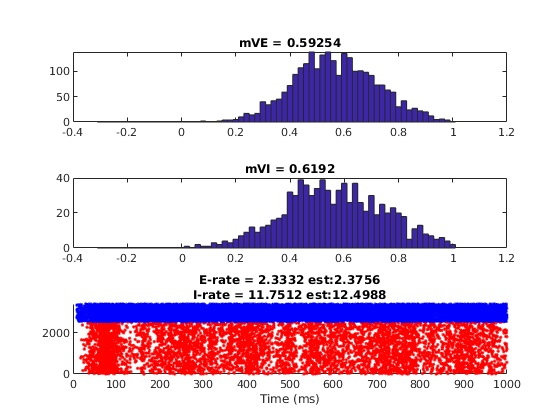

Elapsed time is 3.621052 seconds.


E_Ind = 1:N_E; I_Ind = 1:N_I;

%% Network Simulation
T = 3000; SimulationT = 1000; dt = 0.1;
% E-to-E delay time
T_EEDly = 0.9; N_EEDly = floor(T_EEDly/dt);
T_IEDly = 0.5; N_IEDly = floor(T_IEDly/dt);
T_EIDly = 0.5; N_EIDly = floor(T_EIDly/dt);
% Setup Results Recording
Fr_NW_BG      = zeros(2,1);
mV_NW_BG      = zeros(2,1);
%Fr_OneStep = zeros(2,EITestN,length(S_IEtest)); % one step MF estimation using network mV

N_EE = mean(sum(CS_EE,2)); N_EI = mean(sum(CS_EI,2));
N_IE = mean(sum(CS_IE,2)); N_II = mean(sum(CS_II,2));

% Create sliding windows
sampleT = 200;
Sliding = 100;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);

% The initial states
% load('IniTestSNW.mat');
% RefTimeE = EndState{1}; VE = EndState{2}; SpE = EndState{3}; GE_ampa_R = EndState{4}; GE_nmda_R = EndState{5}; GE_gaba_R = EndState{6};
%                                                              GE_ampa_D = EndState{7}; GE_nmda_D = EndState{8}; GE_gaba_D = EndState{9};
% RefTimeI = EndState{10};VI = EndState{11};SpI = EndState{12};GI_ampa_R = EndState{13};GI_nmda_R = EndState{14};GI_gaba_R = EndState{15};
%                                                              GI_ampa_D = EndState{16};GI_nmda_D = EndState{17};GI_gaba_D = EndState{18};
% if N_EEDly>=size(EndState{19},2)
% EEDlyRcd = [EndState{19},zeros(N_E,N_EEDly-size(EndState{19},2))]; 
% else
%     EEDlyRcd = EndState{19}(:,1:N_EEDly);
% end
% if N_IEDly>=size(EndState{20},2)
% IEDlyRcd = [EndState{20},zeros(N_I,N_IEDly-size(EndState{20},2))]; 
% else
%     IEDlyRcd = EndState{20}(:,1:N_IEDly);
% end
% EIDlyRcd = sparse(N_E,N_EIDly);
%E_SpHis= []; I_SpHis=[];
RefTimeE = zeros(N_E,1); VE = zeros(N_E,1); SpE =zeros(N_E,1); GE_ampa_R = zeros(N_E,1); GE_nmda_R = zeros(N_E,1); GE_gaba_R = zeros(N_E,1);
                                                             GE_ampa_D = zeros(N_E,1); GE_nmda_D = zeros(N_E,1); GE_gaba_D = zeros(N_E,1);
RefTimeI = zeros(N_I,1);VI = zeros(N_I,1);SpI = zeros(N_I,1);GI_ampa_R = zeros(N_I,1);GI_nmda_R = zeros(N_I,1);GI_gaba_R = zeros(N_I,1);
                                                             GI_ampa_D = zeros(N_I,1);GI_nmda_D = zeros(N_I,1);GI_gaba_D = zeros(N_I,1);

EEDlyRcd = sparse(N_E,N_EEDly);                                                             
IEDlyRcd = sparse(N_I,N_IEDly);
EIDlyRcd = sparse(N_E,N_EIDly);

E_Sp = []; I_Sp = [];
VE_T = []; VI_T = [];
sampleN = floor(Sliding/dt); % sample each 2 ms
SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('FrEs',   zeros(size(Wins(:,1))), 'FrIs',   zeros(size(Wins(:,1))),...
    'mVEs',   zeros(size(Wins(:,1))), 'mVIs',   zeros(size(Wins(:,1))));
NWTrace.VEDist =  cell(size(Wins(:,1)));
NWTrace.VIDist =  cell(size(Wins(:,1)));
NWTrace.Wins = Wins;

tic
for TimeN = 1:floor(T/dt)
    [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
        oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
        oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
        oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
        oEEDlyRcd,oIEDlyRcd, oEIDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
        V1NetworkUpdate_Ver3_EEnIEnEIDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
        GE_ampa_D,GE_nmda_D,GE_gaba_D,...
        RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
        GI_ampa_D,GI_nmda_D,GI_gaba_D,...
        EEDlyRcd,IEDlyRcd, EIDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
        CS_EE,CS_EI,CS_IE,CS_II,...
        S_EE,S_EI,S_IE,S_II,...
        tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
        dt,p_EEFail,...
        gL_E,Ve,S_Elgn,rhoE_ampa,rhoE_nmda,...
        gL_I,Vi,S_Ilgn,rhoI_ampa,rhoI_nmda,...
        S_ambU,lambda_E,lambda_I,rE_ambU,rI_ambU,...
        S_EL6U,S_IL6U,rE_L6U,rI_L6U); % L6 Parameters          % The lower/upper bounds for kick waiting time
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd; IEDlyRcd = oIEDlyRcd; EIDlyRcd = oEIDlyRcd;
    
    % When reaching every 500ms, demostrate and pause
    if mod(TimeN,SimulationN) == 0 && TimeN*dt>=400
        ParameterDisp = ['S_EE = ' num2str(S_EE) ', S_EI = ' num2str(S_EI) ...
            ', S_IE = ' num2str(S_IE) ', S_II = ' num2str(S_II) '\n' ...
            'S_Elgn = ' num2str(S_Elgn) ', lambda_E = ' num2str(lambda_E) ...
            ', S_Ilgn = ' num2str(S_Ilgn) ', lambda_I = ' num2str(lambda_I) '\n' ...
            'S_amb = ' num2str(S_amb) ', rE_amb = ' num2str(rE_amb) ', rI_amb = ' num2str(rI_amb)];
        
        fprintf(ParameterDisp)
        figure('Name','TestRaster');
        subplot 311
        hist(oVE,-0.3:0.02:1)
        title(['mVE = ' num2str(nanmean(VE_T))])
        %E_SpHis = [E_SpHis,sum(oSpE)];
        %axis([-0.4 1.1 0 6000])
        
        subplot 312
        hist(oVI,-0.3:0.02:1)
        title(['mVI = ' num2str(nanmean(VI_T))])
              
        %E_Ind = 10000:13000; I_Ind = 3300:4300;
        scatterE = find(ismember(E_Sp(:,1),E_Ind));
        scatterI = find(ismember(I_Sp(:,1),I_Ind));
        [~,E_Fire_Ind] = ismember(E_Sp(scatterE,1),E_Ind);
        [~,I_Fire_Ind] = ismember(I_Sp(scatterI,1),I_Ind);
        
        WinSize = SimulationT;
        T_RateWindow = [TimeN*dt-WinSize TimeN*dt];
        E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
        I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        E_Rate = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
        I_Rate = length(I_SpInd)/(WinSize/1000)/length(I_Ind);
        
        f_EnIOneStep = MeanFieldEst_BkGd_L6_OneStep(N_EE,N_EI,N_IE,N_II,...
                                                    S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                                    lambda_E,S_Elgn,rE_amb,S_amb,...
                                                    lambda_I,S_Ilgn,rI_amb,...
                                                    S_EL6,S_IL6,rE_L6,rI_L6,...
                                                    gL_E,gL_I,Ve,Vi,nanmean(VE_T),nanmean(VI_T));
        %
        subplot 313
        hold on
        scatter(E_Sp(scatterE,2),E_Fire_Ind,'r.')
        scatter(I_Sp(scatterI,2),I_Fire_Ind+max(E_Fire_Ind),'b.');
        title({['E-rate = ' num2str(E_Rate) ' est:' num2str(f_EnIOneStep(1))],['I-rate = ' num2str(I_Rate) ' est:' num2str(f_EnIOneStep(2))]})
        xlabel('Time (ms)')
        xlim(T_RateWindow)
        ylim([0 max(I_Fire_Ind)+max(E_Fire_Ind)])
        drawnow
        %pause
        %close(h)
        % end of 500ms plot
    end
    
    % every 20ms time window
    if mod(TimeN,sampleN) == 0 && TimeN >= floor(sampleT/dt)
        WinSize = NWTrace.Wins(SampleInd,2) - NWTrace.Wins(SampleInd,1);
        T_RateWindow = NWTrace.Wins(SampleInd,:);
        E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
        I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        
        NWTrace.FrEs(SampleInd) = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
        NWTrace.FrIs(SampleInd) = length(I_SpInd)/(WinSize/1000)/length(I_Ind);
        NWTrace.mVEs(SampleInd) = nanmean(oVE(E_Ind));
        NWTrace.mVIs(SampleInd) = nanmean(oVI(I_Ind));
        
        NWTrace.VEDist{SampleInd} = oVE(E_Ind);
        NWTrace.VIDist{SampleInd} = oVI(I_Ind);
        
        SampleInd = SampleInd + 1;
        toc
    end
    
    E_Sp = [E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]];
    I_Sp = [I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]];
    VE_T = [VE_T;nanmean(oVE(E_Ind))];
    VI_T = [VI_T;nanmean(oVI(I_Ind))];
    
%     if sum(isnan(oVE))>0.80*N_E
%         BlowUp = true;
%         disp('warning!: Network exploded')
%         break
%     end
    
    % the end of iteration
end

toc

NWTrace.E_Sp = E_Sp; NWTrace.I_Sp = I_Sp;


% If blown up, discard other recordings...
if ~BlowUp
    Fr_NW_BG     = [E_Rate;I_Rate];
    mV_NW_BG     = [nanmean(VE_T),nanmean(VI_T)];
    %Fr_OneStep(:,S_EIInd,S_IEInd) = f_EnIOneStep;
end
% end of S_IE loop


## Now, with drive

LGN & L6 input classified by domains

Inputs are high now!!! Bernouli may underestimate, and we need to use:

- first simulate Poisson processes

- Feed them to the new function

- Kicks are all normalized to LGN sizes

DomInd = 1; % 1 for opt, 2 and 4 for sub-opt, 3 for worst;
%DriveE = [60,53,48,53]*4/1e3; % Ordered by domains, times the number of lgn cells, normalized by 1000ms
lgnE_DriveOrg = [60,50,42,50]; % The original Large LGN input before subtraction, per LGN cell, before normaliztion
lgn_spon = 20;
% Plan F'1-3: 1.6 but Reducing Drive
DriveChoice = 1; % 1 for high, original
               % 2 for medium, 2/3 after subtraction
               % 3 for small, 1/3 after subtraction
               % 4 for extra small, 1/8 after subtraction
switch DriveChoice
    case 1
        lgnE_Drive =              lgnE_DriveOrg               *4/1e3;
    case 2
        lgnE_Drive = (lgn_spon + (lgnE_DriveOrg-lgn_spon)*2/3)*4/1e3;
    case 3
        lgnE_Drive = (lgn_spon + (lgnE_DriveOrg-lgn_spon)*1/3)*4/1e3;
    case 4
        lgnE_Drive = (lgn_spon + (lgnE_DriveOrg-lgn_spon)*1/8)*4/1e3;
end

lgnI_Drive = min(lgnE_Drive);
lambda_E_drive = lgnE_Drive(DomInd);
lambda_I_drive = lgnI_Drive;

L6E_DriveOrg = [50 35 20 35];
L6E_spon = 5;
switch DriveChoice
    case 1
        L6E_Drive =             L6E_DriveOrg              *50/1e3;
    case 2
        L6E_Drive = (L6E_spon + (L6E_DriveOrg-L6E_spon)*2/3)*50/1e3;
    case 3
        L6E_Drive = (L6E_spon + (L6E_DriveOrg-L6E_spon)*1/3)*50/1e3;
    case 4
        L6E_Drive = (L6E_spon + (L6E_DriveOrg-L6E_spon)*1/8)*50/1e3;
end

%L6I_Drive = min(L6E_Drive);
rE_L6_DriveU = L6E_Drive(DomInd)*S_EL6/S_EL6U;
rI_L6_DriveU = 3*L6E_Drive(DomInd)*S_IL6/S_IL6U;
%rI_L6_DriveU = 3*rE_L6_DriveU*S_IL6/S_IL6U; % This was wrong for Dp-Fp4


% Making Poisson here/Reading
T = 50000; dt = 0.1;
TimeFrac = 0.05;
% E-to-E delay time
T_EEDly = .9; N_EEDly = floor(T_EEDly/dt);
T_IEDly = .5; N_IEDly = floor(T_IEDly/dt);
T_EIDly = .5; N_EIDly = floor(T_EIDly/dt);
% Partition of Time into 10 pieces
TPar = 10;
TSimOne = floor(T/TPar/1e3);
save(['DataSNW_Pars_' DataSuffix num2str(DriveChoice) '.mat'])

Simulation of Drive

Then make a transfer between neurons in HCs and 10*10 pixels

LGNCurInp = 0;

lgnE_Events = PoissonInputForNetwork(N_E,lambda_E_drive*(1-LGNCurInp),T*TimeFrac,dt);
lgnI_Events = PoissonInputForNetwork(N_I,lambda_I_drive*(1-LGNCurInp),T*TimeFrac,dt);
AmbE_Events = PoissonInputForNetwork(N_E,rE_ambU,T*TimeFrac,dt);
AmbI_Events = PoissonInputForNetwork(N_I,rI_ambU,T*TimeFrac,dt);

% L6 is much more specific!!! We will make a sum of Poisson and constant
L6CurInp = 0;
L6E_Events  = PoissonInputForNetwork(N_E,rE_L6_DriveU*(1-L6CurInp),T*TimeFrac,dt);
L6I_Events  = PoissonInputForNetwork(N_I,rI_L6_DriveU*(1-L6CurInp),T*TimeFrac,dt);

%   [A,~,Times] = find(eventsN);
% % The initial states
% InSs = load('Initials_L6.mat');
% RefTimeE = InSs.RefTimeE; VE = InSs.VE; SpE = InSs.SpE; GE_ampa_R = InSs.GE_ampa_R; GE_nmda_R = InSs.GE_nmda_R; GE_gaba_R = InSs.GE_gaba_R;
% GE_ampa_D = InSs.GE_ampa_D; GE_nmda_D = InSs.GE_nmda_D; GE_gaba_D = InSs.GE_gaba_D;
% RefTimeI = InSs.RefTimeI; VI = InSs.VI; SpI = InSs.SpI; GI_ampa_R = InSs.GI_ampa_R; GI_nmda_R = InSs.GI_nmda_R; GI_gaba_R = InSs.GI_gaba_R;
% GI_ampa_D = InSs.GI_ampa_D; GI_nmda_D = InSs.GI_nmda_D; GI_gaba_D = InSs.GI_gaba_D;
% EEDlyRcd = sparse(N_E,N_EEDly);

%load('IniTestSNW_Dp.mat','EndState');
% RefTimeE = EndState{1}; VE = EndState{2}; SpE = EndState{3}; GE_ampa_R = EndState{4}; GE_nmda_R = EndState{5}; GE_gaba_R = EndState{6};
%                                                              GE_ampa_D = EndState{7}; GE_nmda_D = EndState{8}; GE_gaba_D = EndState{9};
% RefTimeI = EndState{10}; VI = EndState{11}; SpI = EndState{12}; GI_ampa_R = EndState{13}; GI_nmda_R = EndState{14}; GI_gaba_R = EndState{15};
%                                                                 GI_ampa_D = EndState{16}; GI_nmda_D = EndState{17}; GI_gaba_D = EndState{18};
% if N_EEDly>=size(EndState{19},2)
% EEDlyRcd = [EndState{19},zeros(N_E,N_EEDly-size(EndState{19},2))]; 
% else
%     EEDlyRcd = EndState{19}(:,1:N_EEDly);
% end
% if N_IEDly>=size(EndState{20},2)
% IEDlyRcd = [EndState{20},zeros(N_I,N_IEDly-size(EndState{20},2))]; 
% else
%     IEDlyRcd = EndState{20}(:,1:N_IEDly);
% end
% if N_EIDly>=size(EndState{21},2)
% EIDlyRcd = [EndState{21},zeros(N_E,N_EIDly-size(EndState{20},2))]; 
% else
%     EIDlyRcd = EndState{21}(:,1:N_EIDly);
% end
%EIDlyRcd = repmat(CS_EI*SpI,1,N_EIDly);
% The initial states, for more simulation 
load(['DriveWk_SNW_Sp_TestDly_EE0.9_IE0.5_NMDA80_30-35_Dpp1.mat'],'EndState')
[RefTimeE, VE, SpE, GE_ampa_R, GE_nmda_R, GE_gaba_R, GE_ampa_D, GE_nmda_D, GE_gaba_D,...
          RefTimeI, VI, SpI, GI_ampa_R, GI_nmda_R, GI_gaba_R, GI_ampa_D, GI_nmda_D, GI_gaba_D,...
          EEDlyRcd, IEDlyRcd, EIDlyRcd]...
         = CostrNewIC(EndState,N_E,N_I,N_EEDly,N_IEDly,N_EIDly);

% Create sliding windows
sampleT = 200;
Sliding = 200;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);
WinNum = length(Wins);
sampleN = floor(Sliding/dt); % sample each 2 ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1));
%NWTrace.Wins = {Wins};

MaxInpBin = floor(T*TimeFrac/dt);

The biggest problem here is the access to the input matrices

So I do the following:

For every 100ms (1000 bins), first pre-compute input matrices for all (E ampa, Enmda, Iampa, Inmda), then feed into iteration algorithm

But to accelerate, we exclude L6 Current Input at first...

## Simulations of drive

for TSec = 1:TPar
tic
for TimeN = 1:floor(T/dt/TPar)
    % First, Get input matrices from series
    InpWin = 100; FrameNum = floor(InpWin/dt);
    FrameInd = mod(TimeN, FrameNum);
    if FrameInd == 0
    FrameInd = FrameNum;
    end
    RandTimBin = randi([1 MaxInpBin+1],6,FrameNum);
    if FrameInd  == 1 % if the first frame, recompute input mats
        EampaInp = single(full(S_Elgn * (lgnE_Events(:,RandTimBin(1,:)) + lambda_E_drive*dt*LGNCurInp) ...
                      + S_ambU  * AmbE_Events(:,RandTimBin(3,:)) ...
                      + S_EL6U  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_DriveU*dt*L6CurInp) * rhoE_ampa)); %  * rhoE_ampa
        IampaInp = single(full(S_Ilgn * (lgnI_Events(:,RandTimBin(2,:)) + lambda_I_drive*dt*LGNCurInp) ...
                      + S_ambU  * AmbI_Events(:,RandTimBin(4,:)) ...
                      + S_IL6U  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_DriveU*dt*L6CurInp) * rhoI_ampa)); %  * rhoI_ampa
        
        EnmdaInp = single(full(S_EL6U  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_DriveU*dt*L6CurInp) * rhoE_nmda)); % 
        InmdaInp = single(full(S_IL6U  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_DriveU*dt*L6CurInp) * rhoI_nmda));
        
    end
    
   
%      lgnEVec = zeros(N_E,1);lgnIVec = zeros(N_I,1);
%      AmbEVec = zeros(N_E,1);AmbIVec = zeros(N_I,1);
%      L6EVec = zeros(N_E,1); L6IVec = zeros(N_I,1);
     
   [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
                             oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
          oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
                             oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
                             oEEDlyRcd,oIEDlyRcd, oEIDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
   V1NetworkUpdate_Ver3_Drive_PoissonRead_EEnIEnEIDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
                                          GE_ampa_D,GE_nmda_D,GE_gaba_D,...
                          RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
                                          GI_ampa_D,GI_nmda_D,GI_gaba_D,...
                                          EEDlyRcd,IEDlyRcd, EIDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
                          CS_EE,CS_EI,CS_IE,CS_II,...
                          S_EE,S_EI,S_IE,S_II,...
                          tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
                          dt,p_EEFail,...
                          gL_E,Ve,rhoE_ampa,rhoE_nmda,...
                          gL_I,Vi,rhoI_ampa,rhoI_nmda,...
                          EampaInp(:,FrameInd), IampaInp(:,FrameInd),...
                          EnmdaInp(:,FrameInd), InmdaInp(:,FrameInd));
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd; IEDlyRcd = oIEDlyRcd; EIDlyRcd = oEIDlyRcd;
    
     
    % Record Every Time time window
    RecordNum = floor(sampleT/dt);
    RecordInd = mod(TimeN, RecordNum);
    SampleRate = 0.5;
    if RecordInd == 1
        clear E_Sp I_Sp mVETemp mVITemp
        E_Sp = [];
        I_Sp = [];
        mVETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        mVITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        mVRecordInd = 1;        
    elseif RecordInd == 0 
        NWTrace(SampleInd).mVEs = mVETemp;
        NWTrace(SampleInd).mVIs = mVITemp;
        
        NWTrace(SampleInd).SpEs = E_Sp;
        NWTrace(SampleInd).SpIs = I_Sp;
        % print some info here      
        SampleInd = SampleInd + 1
        %sum(isnan(oVE))/N_E 
        FrENow = size(E_Sp,1)/N_E/sampleT*1000
        FrINow = size(I_Sp,1)/N_I/sampleT*1000
    end
    E_Sp = single([E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]]);
    I_Sp = single([I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]]);
    
    if mod(TimeN,floor(1/SampleRate)) == 1
        mVETemp(:,mVRecordInd) = oVE;
        mVITemp(:,mVRecordInd) = oVI;
        mVRecordInd = mVRecordInd + 1; 
    end
    
%     if sum(isnan(oVE))>0.80*N_E
%         BlowUp = true;
%         disp('warning!: Network exploded')
%         break
%     end
    
    % the end of iteration
end
toc
%DataFolder = [pwd '/Figures/Demo042221/'];
text = sprintf('DriveWk_SNW_Sp_TestDly_EE%.1f_IE%.1f_NMDA%d_%d-%d_%s%d.mat',T_EEDly,T_IEDly, tau_nmda_D,...
                                                            TSimOne*(TSec-1),TSimOne*TSec, DataSuffix, DriveChoice);
EndState = {RefTimeE, VE, SpE, GE_ampa_R, GE_nmda_R, GE_gaba_R, GE_ampa_D, GE_nmda_D, GE_gaba_D,...
            RefTimeI, VI, SpI, GI_ampa_R, GI_nmda_R, GI_gaba_R, GI_ampa_D, GI_nmda_D, GI_gaba_D,...
            EEDlyRcd, IEDlyRcd, EIDlyRcd};
save([DataFolder text],'NWTrace','EndState','-v7.3')

clear NWTrace
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1));
end

SampleInd = 2

FrENow = 26.2337

FrINow = 103.6434

SampleInd = 3

FrENow = 27.2898

FrINow = 106.5818

SampleInd = 4

FrENow = 27.8602

FrINow = 107.8377

SampleInd = 5

FrENow = 27.1753

FrINow = 106.2204

SampleInd = 6

FrENow = 24.9763

FrINow = 100.9360

SampleInd = 7

FrENow = 26.8674

FrINow = 105.7879

SampleInd = 8

FrENow = 26.7904

FrINow = 106.0900

SampleInd = 9

FrENow = 410.8863

FrINow = 448.1872

SampleInd = 10

FrENow = 475.7422

FrINow = 499.8993

## Load data

DataSuffix = 'Dp';
DriveChoice = '';
%DataFolder = [pwd '/Figures/Demo042221/'];
TPar = 10;
% read data, and get spike and mV
SpE = []; SpI = [];
mVE = []; mVI = []; % These are the total data
for TSec = 1:TPar
    text = sprintf('DriveWk_SNW_Sp_TestDly_EE%.1f_IE%.1f_NMDA%d_%d-%d_%s%s.mat',T_EEDly,T_IEDly, tau_nmda_D,...
                                                            TSimOne*(TSec-1),TSimOne*TSec, DataSuffix, DriveChoice);
    load([DataFolder text],'NWTrace');
    SpECurrent = []; SpICurrent = [];
    mVECurrent = []; mVICurrent = [];
    for WinInd = 1:length(NWTrace)
    SpECurrent = [SpECurrent; NWTrace(WinInd).SpEs];
    SpICurrent = [SpICurrent; NWTrace(WinInd).SpIs];
    mVECurrent = [mVECurrent, NWTrace(WinInd).mVEs];
    mVICurrent = [mVICurrent, NWTrace(WinInd).mVIs];
    end
    SpECurrent(:,2) = SpECurrent(:,2) + (TSec-1)*T/TPar;
    SpICurrent(:,2) = SpICurrent(:,2) + (TSec-1)*T/TPar;
    SpE = [SpE;SpECurrent];
    SpI = [SpI;SpICurrent];
    mVE = [mVE,mVECurrent];
    mVI = [mVI,mVICurrent];
end
WinNum = size(mVE,2);
StatWin = linspace(0,T,WinNum+1);
WinSize = StatWin(2) - StatWin(1);

SNWData.VE = nanmean(mVE);
SNWData.VI = nanmean(mVI);
SNWData.SpE = histcounts(SpE(:,2),StatWin);
SNWData.SpI = histcounts(SpI(:,2),StatWin);
clear mVE mVI SpE SpI

## Figures 

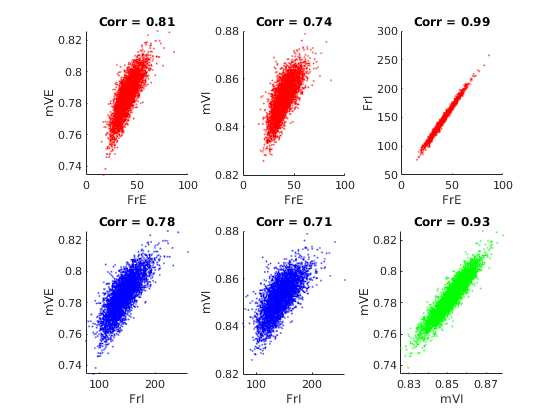

Res = 10; %change bin resolution to 4ms
NewBinSz = floor(Res/WinSize);
Len = length(StatWin)-1;
SNWDataRes.SpE = mean(reshape(SNWData.SpE,NewBinSz,floor(Len/NewBinSz)),1);
SNWDataRes.SpI = mean(reshape(SNWData.SpI,NewBinSz,floor(Len/NewBinSz)),1);
SNWDataRes.VE = mean(reshape(SNWData.VE,NewBinSz,floor(Len/NewBinSz)),1);
SNWDataRes.VI = mean(reshape(SNWData.VI,NewBinSz,floor(Len/NewBinSz)),1);
hCorr_Bin = CorrCoefFig(SNWDataRes.SpE/N_E/WinSize*1e3, SNWDataRes.SpI/N_I/WinSize*1e3,...
                    SNWDataRes.VE,                  SNWDataRes.VI);

### Then we check how things goes within each large Bin

By removing the sliding mean

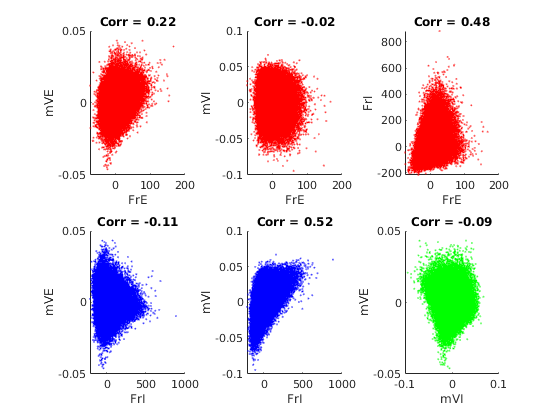

SNWDataFilt.SpE = SNWData.SpE - reshape(repmat(SNWDataRes.SpE,NewBinSz,1),1,length(SNWData.SpE));
SNWDataFilt.SpI = SNWData.SpI - reshape(repmat(SNWDataRes.SpI,NewBinSz,1),1,length(SNWData.SpI));
SNWDataFilt.VE = SNWData.VE - reshape(repmat(SNWDataRes.VE,NewBinSz,1),1,length(SNWData.VE));
SNWDataFilt.VI = SNWData.VI - reshape(repmat(SNWDataRes.VI,NewBinSz,1),1,length(SNWData.VI));
hCorr_Filt = CorrCoefFig(SNWDataFilt.SpE/N_E/WinSize*1e3, SNWDataFilt.SpI/N_I/WinSize*1e3,...
                         SNWDataFilt.VE,                  SNWDataFilt.VI);


f_pre = [mean(SNWDataRes.SpE/N_E/WinSize*1e3);
         mean(SNWDataRes.SpI/N_I/WinSize*1e3)]

f_pre =    40.2403
  143.5520


mVE = mean(SNWDataRes.VE); mVI = mean(SNWDataRes.VI);

Smth = 20;
SNWDataSmth.VE = conv(SNWData.VE,1/Smth*ones(1,Smth)); SNWDataSmth.VE = SNWDataSmth.VE(Smth:end-Smth+1);
SNWDataSmth.VI = conv(SNWData.VI,1/Smth*ones(1,Smth)); SNWDataSmth.VI = SNWDataSmth.VI(Smth:end-Smth+1);
SNWDataSmth.SpE = conv(SNWData.SpE,1/Smth*ones(1,Smth)); SNWDataSmth.SpE = SNWDataSmth.SpE(Smth:end-Smth+1);
SNWDataSmth.SpI = conv(SNWData.SpI,1/Smth*ones(1,Smth)); SNWDataSmth.SpI = SNWDataSmth.SpI(Smth:end-Smth+1);

### Time Traces

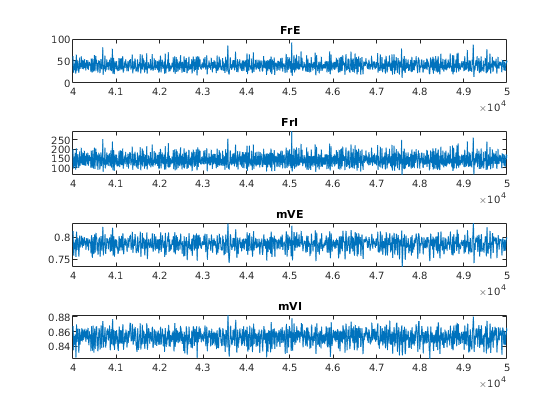

figure("Name",'Traj on Time')
subplot 411
plot(StatWin(1:length(SNWDataSmth.SpE)),SNWDataSmth.SpE/N_E/WinSize*1e3)
title('FrE');xlim([4e4 5e4])
subplot 412
plot(StatWin(1:length(SNWDataSmth.SpE)),SNWDataSmth.SpI/N_I/WinSize*1e3)
title('FrI');xlim([4e4 5e4])
subplot 413
plot(StatWin(1:length(SNWDataSmth.SpE)),SNWDataSmth.VE)
title('mVE');xlim([4e4 5e4])
subplot 414
plot(StatWin(1:length(SNWDataSmth.SpE)),SNWDataSmth.VI)
title('mVI');xlim([4e4 5e4])

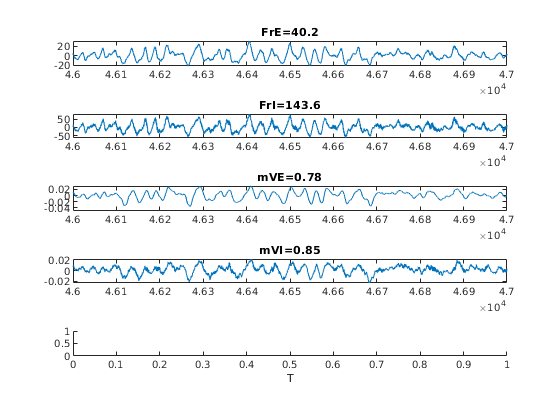


figure("Name",'Raster')
Xrange = [46000 47000];
subplot 511
plot(StatWin(1:length(SNWDataSmth.SpE)),SNWDataSmth.SpE/N_E/WinSize*1e3-f_pre(1))
title(sprintf('FrE=%.1f',f_pre(1)));xlim(Xrange)
subplot 512
plot(StatWin(1:length(SNWDataSmth.SpE)),SNWDataSmth.SpI/N_I/WinSize*1e3-f_pre(2))
title(sprintf('FrI=%.1f',f_pre(2)));xlim(Xrange)
subplot 513
plot(StatWin(1:length(SNWDataSmth.SpE)),SNWDataSmth.VE-mVE)
title(sprintf('mVE=%.2f',mVE));xlim(Xrange)
subplot 514
plot(StatWin(1:length(SNWDataSmth.SpE)),SNWDataSmth.VI-mVI)
title(sprintf('mVI=%.2f',mVI));xlim(Xrange)
subplot 515
hold on
%ENeu = floor(N_E/2):N_E; INeu = 1:floor(N_I/2);
% scatter(SpE(:,2), SpE(:,1),0.1 ,'r.')
% scatter(SpI(:,2), SpI(:,1)+max(SpE(:,1)) , 0.1,'b.')
% xlim(Xrange); ylim([floor(N_E*2/3),N_E+floor(N_I/3)])
xlabel('T')

Spectrogram

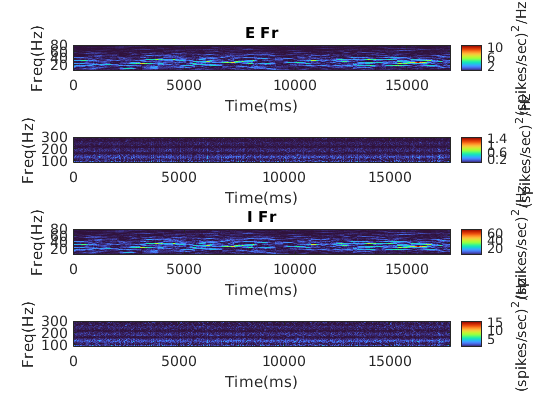

param1.spectrogram_timewindow = 1000;
param1.sdbin = T/WinNum;
param1.frequency_range = [1 80];
param1.duration = [];
param2 = param1; param2.frequency_range = [80,300];
param2.spectrogram_timewindow = 100;
figure('Name','Spectrogram')
subplot 411
spgE1=spectrogram(SNWData.SpE(15e4:24e4)/N_E/WinSize*1e3,param1);
title('E Fr')
subplot 412
spgE2=spectrogram(SNWData.SpE(15e4:24e4)/N_E/WinSize*1e3,param2);

%set(gca,'ColorScale','log')
subplot 413
spgI1=spectrogram(SNWData.SpI(15e4:24e4)/N_I/WinSize*1e3,param1);
title('I Fr')
subplot 414
spgI2=spectrogram(SNWData.SpI(15e4:24e4)/N_I/WinSize*1e3,param2);


%set(gca,'ColorScale','log')
